# MAT143 Proje

Bu projede LeBron James'in sezon bazında maç başına sayılarını 12 yıllık bir süreç içerisinde değerlendirip, gelecekteki veriler için lineer cebir metodlarını kullanarak tahminde bulunacağız. 

İlk önce verimizi MATLAB ortamına iki vektör olarak giriyoruz. Burada x, LeBron'un ligdeki kaçıncı sezonu olduğunu gösterirken, y'de o sezonda LeBron'un kaç sayı averajladığını gösteriyor.

clear
clc

x = 7: 18;
y = [29.7 26.7 27.1 26.8 27.1 25.3 25.3 26.4 27.5 27.4 25.3 25.0];

Veri kümemizi daha iyi anlayabilmek adına bir grafik çizdiriryoruz.

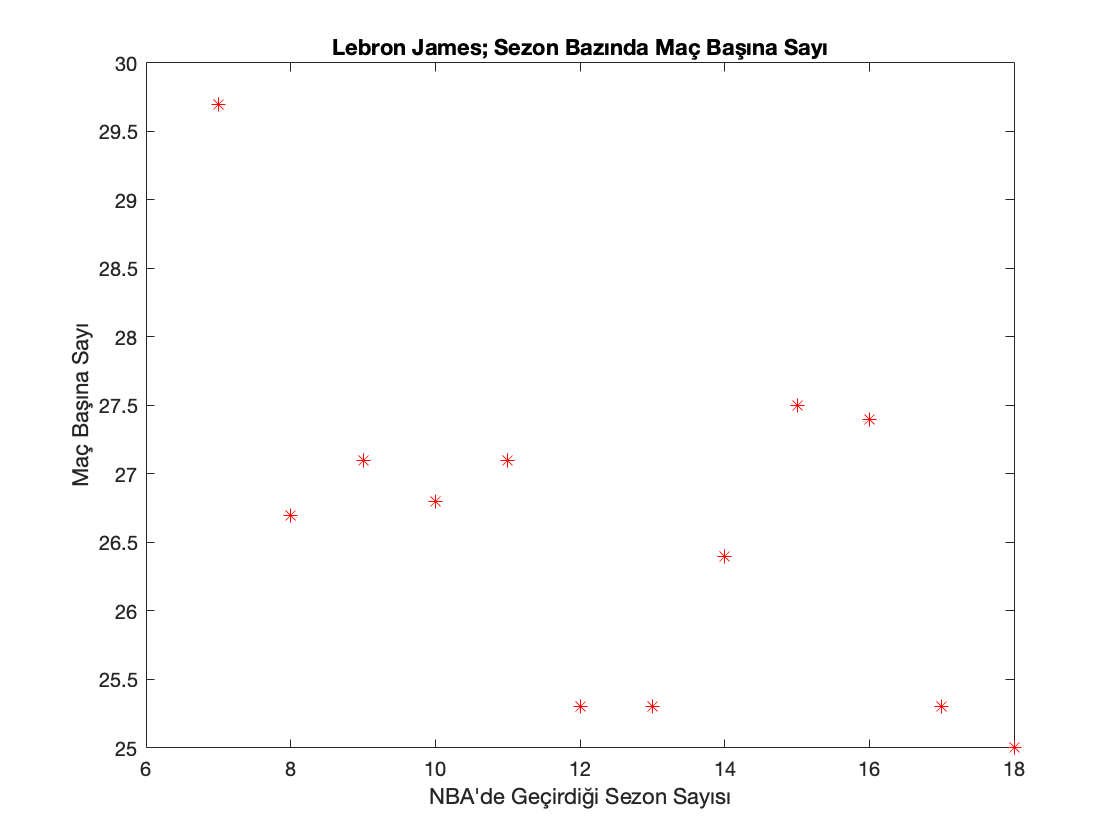

plot(x, y, "*r");
title("Lebron James; Sezon Bazında Maç Başına Sayı");
xlabel("NBA'de Geçirdiği Sezon Sayısı");
ylabel("Maç Başına Sayı");

Sonrasında bu veri kümemizi modelleyebilecek 4 adet uygun fonksiyon seçmemiz gerekiyor. Grafikte görüldüğü gibi eğri polinomsal ve trigonometrik özellikleri net olarak olmasa da göstermekte. Seçilen 4 adet fonksiyon bu durum göz önünde nulunarak çeşitli seçilmelidir.

Seçilen fonksiyonlar;

1) y = A*x^2 + B*x + C;

2) y = A*x^3 + B*x^2 + C*x + D;

3) y = A*x^4 + B*x^3 + C*x^2 + D*x + E;

4) y = A*sin(x) + B*cos(x) + C*x + D;

(Trigonometrik fonksiyonlar x değerlerini radyan olarak değerlendirmektedir.)

Şimdi bu fonksiyonlar için en küçük kareler (least squares) metodunu uygulayarak A, B, C katsayılarını sırasıyla bulacağız.

1) y = A*x^2 + B*x + C için:

Burda c1 vektörü katsayıları tutar.

n = length(x);

A = [n sum(x) sum(x.^2);
    sum(x) sum(x.^2) sum(x.^3);
    sum(x.^2) sum(x.^3) sum(x.^4)];

b = [sum(y);
    sum(y.*x);
    sum(y.*(x.^2))];

c1 = linsolve(A, b);

fprintf("1. fonksiyon: y = %f*x^2 + %f*x + %f\n", c1(3), c1(2), c1(1));

1. fonksiyon: y = 0.029321*x^2 + -0.945604*x + 33.522627


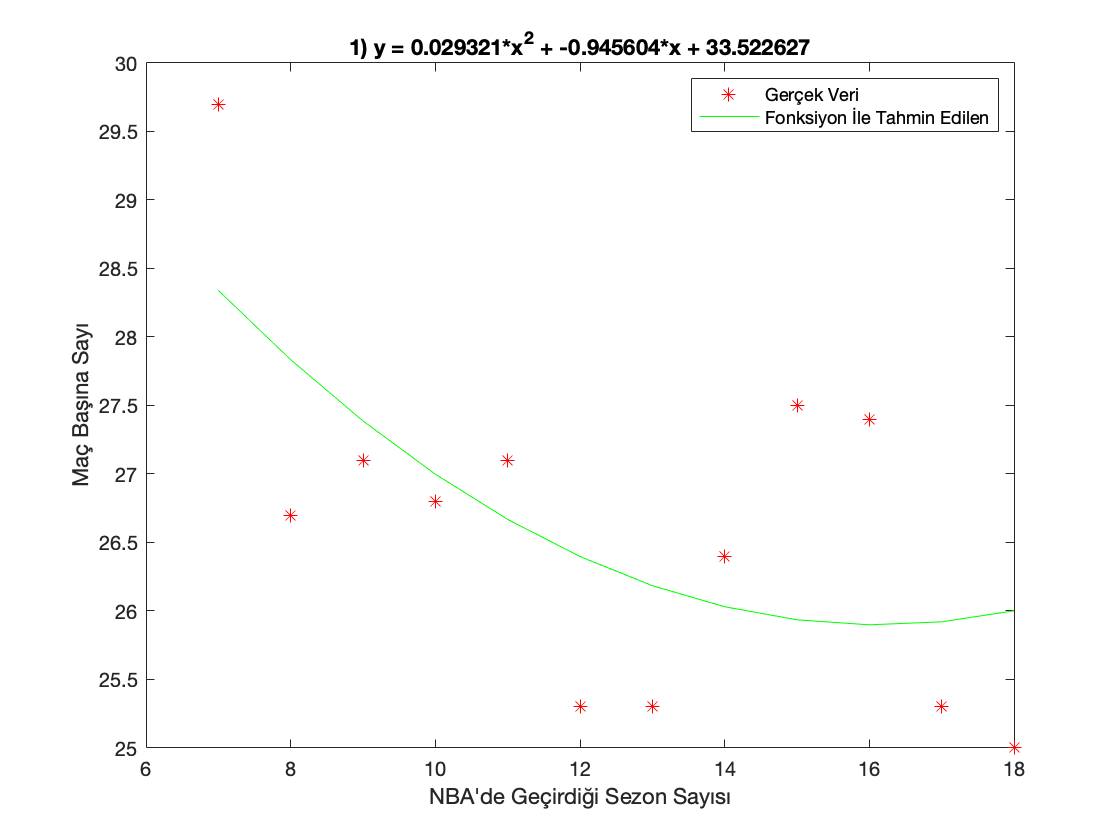


ypred1 = c1(3)*x.^2 + c1(2)*x + c1(1);
plot(x, y, "*r");
hold on
plot(x, ypred1, "g");
title("1) y = 0.029321*x^2 + -0.945604*x + 33.522627");
xlabel("NBA'de Geçirdiği Sezon Sayısı");
ylabel("Maç Başına Sayı");
legend("Gerçek Veri", "Fonksiyon İle Tahmin Edilen")
hold off

2) y = A*x^3 + B*x^2 + C*x + D için;

Burda c2 vektörü katsayıları tutar.

n = length(x);

A = [n sum(x) sum(x.^2) sum(x.^3);
    sum(x) sum(x.^2) sum(x.^3) sum(x.^4);
    sum(x.^2) sum(x.^3) sum(x.^4) sum(x.^5)
    sum(x.^3) sum(x.^4) sum(x.^5) sum(x.^6)];

b = [sum(y);
    sum(y.*x);
    sum(y.*(x.^2));
    sum(y.*(x.^3))];

c2 = linsolve(A, b);

fprintf("2. fonksiyon: y = %f*x^3 + %f*x^2 + %f*x + %f\n", c2(4), c2(3), c2(2), c2(1));

2. fonksiyon: y = -0.020901*x^3 + 0.813120*x^2 + -10.298945*x + 68.793606


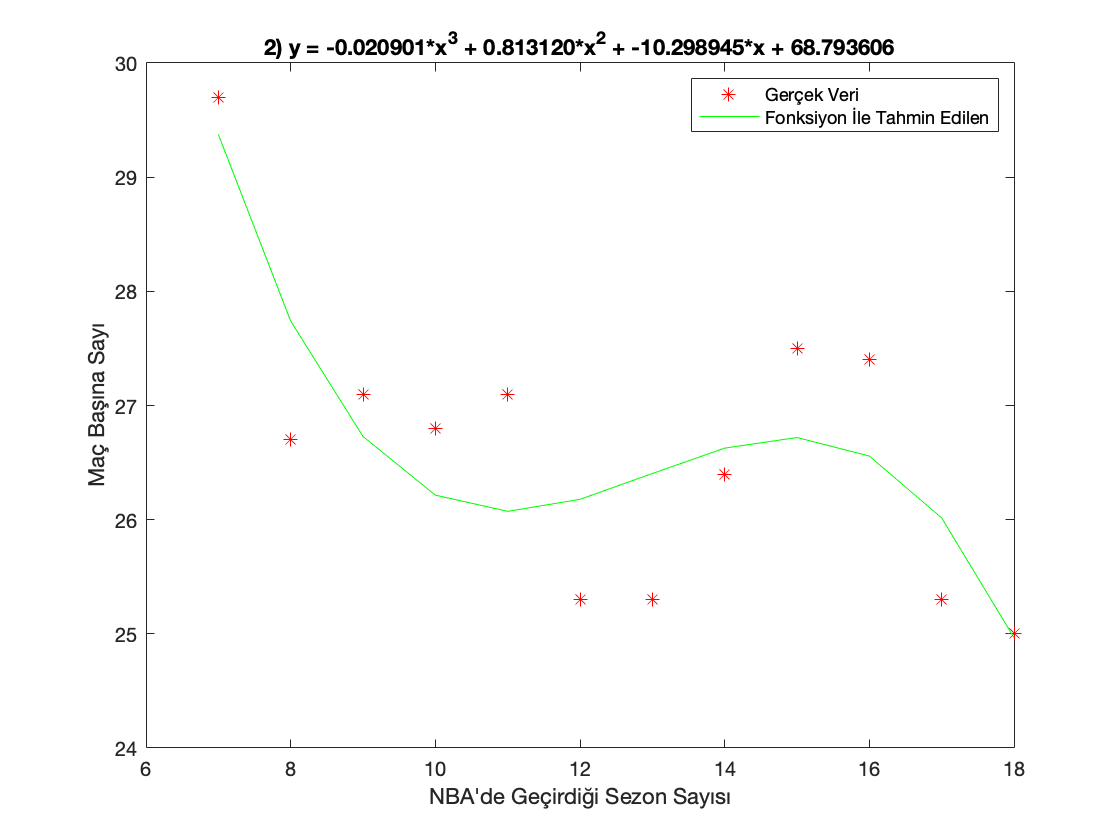


ypred2 = c2(4)*x.^3 + c2(3)*x.^2 + c2(2)*x + c2(1);
plot(x, y, "*r");
hold on
plot(x, ypred2, "g");
title("2) y = -0.020901*x^3 + 0.813120*x^2 + -10.298945*x + 68.793606");
xlabel("NBA'de Geçirdiği Sezon Sayısı");
ylabel("Maç Başına Sayı");
legend("Gerçek Veri", "Fonksiyon İle Tahmin Edilen");
hold off

3) y = A*x^4 + B*x^3 + C*x^2 + D*x + E için;

Burda c3 vektörü katsayıları tutar.

n = length(x);

A = [n sum(x) sum(x.^2) sum(x.^3) sum(x.^4);
    sum(x) sum(x.^2) sum(x.^3) sum(x.^4) sum(x.^5);
    sum(x.^2) sum(x.^3) sum(x.^4) sum(x.^5) sum(x.^6);
    sum(x.^3) sum(x.^4) sum(x.^5) sum(x.^6) sum(x.^7);
    sum(x.^4) sum(x.^5) sum(x.^6) sum(x.^7) sum(x.^8)];

b = [sum(y);
    sum(y.*x);
    sum(y.*(x.^2));
    sum(y.*(x.^3));
    sum(y.*(x.^4))];

c3 = linsolve(A, b);

fprintf("3. fonksiyon: y = %f*x^4 + %f*x^3 + %f*x^2 + %f*x + %f\n", c3(5), c3(4), c3(3), c3(2), c3(1));

3. fonksiyon: y = -0.001621*x^4 + 0.060137*x^3 + -0.657849*x^2 + 1.150673*x + 36.635577


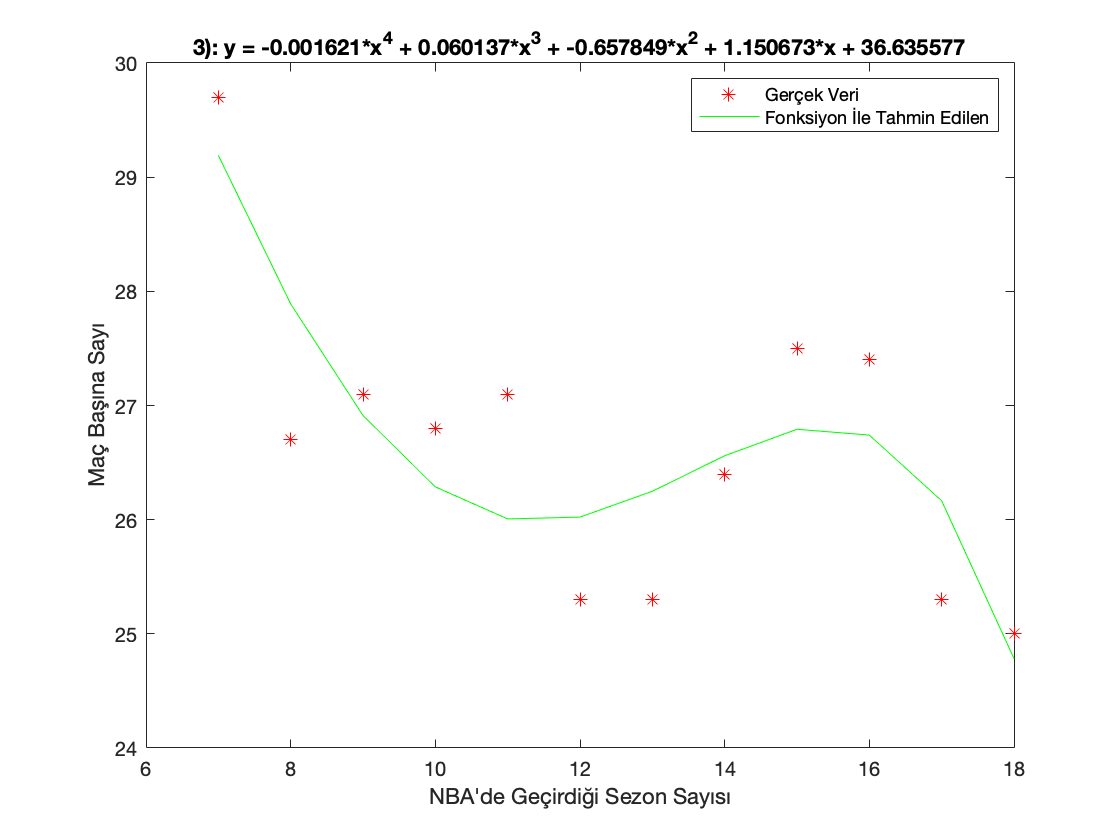


ypred3 =  c3(5)*x.^4 + c3(4)*x.^3 + c3(3)*x.^2 + c3(2)*x + c3(1);
plot(x, y, "*r");
hold on
plot(x, ypred3, "g");
title("3): y = -0.001621*x^4 + 0.060137*x^3 + -0.657849*x^2 + 1.150673*x + 36.635577");
xlabel("NBA'de Geçirdiği Sezon Sayısı");
ylabel("Maç Başına Sayı");
legend("Gerçek Veri", "Fonksiyon İle Tahmin Edilen");
hold off

4) y = A*sin(x) + B*cos(x) + C*x + D için;

Burda c4 vektörü katsayıları tutar.

A = [n sum(x) sum(cos(x)) sum(sin(x));
    sum(x) sum(x.^2) sum(x.*cos(x)) sum(x.*sin(x));
    sum(cos(x)) sum(cos(x).*x) sum(cos(x).^2) sum(cos(x).*sin(x));
    sum(sin(x)) sum(sin(x).*x) sum(sin(x).*cos(x)) sum(cos(x).^2)];

b = [sum(y);
    sum(y.*x);
    sum(y.*(cos(x)));
    sum(y.*sin(x))];

c4 = linsolve(A, b);

fprintf("4. fonksiyon: y = 0.395494*sin(x) + -0.512739*cos(x) + -0.180939*x + 28.868949");

4. fonksiyon: y = 0.395494*sin(x) + -0.512739*cos(x) + -0.180939*x + 28.868949

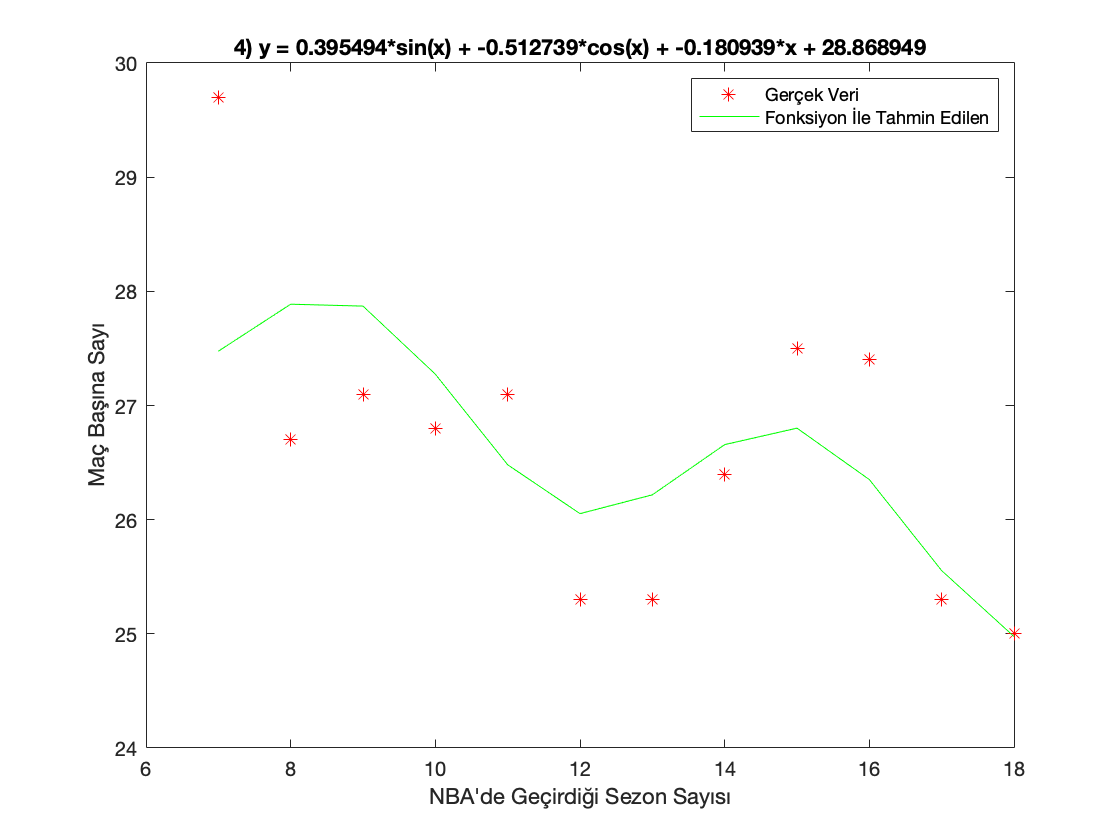


ypred4 = c4(4)*sin(x) + c4(3)*cos(x) + c4(2)*x + c4(1);
plot(x, y, "*r");
hold on
plot(x, ypred4, "g");
title("4) y = 0.395494*sin(x) + -0.512739*cos(x) + -0.180939*x + 28.868949");
xlabel("NBA'de Geçirdiği Sezon Sayısı");
ylabel("Maç Başına Sayı");
legend("Gerçek Veri", "Fonksiyon İle Tahmin Edilen");
hold off

Sonrasında fonksiyonlarımızın verimizi ne kadar iyi modellediği hakkında fikir sahibi olmak adına RMSE (Root Mean Square Error) hesabı yapıyoruz.

rmse1 = sqrt(sum((ypred1 - y).^2) / n)

rmse1 = 0.9856

rmse2 = sqrt(sum((ypred2 - y).^2) / n)

rmse2 = 0.7414

rmse3 = sqrt(sum((ypred3 - y).^2) / n)

rmse3 = 0.7274

rmse4 = sqrt(sum((ypred4 - y).^2) / n)

rmse4 = 0.9438

Görüldüğü üzere trigonometrik ögelere sahip olan fonksiyon 2. derece polinomdan sonra en fazla hata oranına sahip fonksiyon, bu sebeple tahminlerimizin doğru olmadığını 3. ve 4. polinomların datamızı modelleme adına daha iyi bir iş çıkardığını söylemek mümkün. En az hata oranına sahip fonksiyon 3) y = A*x^4 + B*x^3 + C*x^2 + D*x + E  olduğu için bundan sonraki aşamalarda bu fonksiyonu kullanarak işlemlerimizi gerçekleştireceğiz.

Bundan sonraki aşamada iç çarpım tanımlamak üzere gereken verileri MATLAB ortamına giriyoruz.

years = x;
points = y;

d=ones(1,n);
xx=[years.^4;years.^3;years.^2;years;d];
xxt=xx';
e1=[years.^4]';
e2=[years.^3]';
e3=[years.^2]';
e4=[years]';
e5=[d]';

Gerekli verileri girdikten sonra R^12 uzayında doğal iç çarpımı tanımlıyoruz.

r1 = e1;
r2 = (e2 - dot(e2,r1)/dot(r1,r1) .* r1);
r3 = (e3 - dot(e3,r1)/dot(r1,r1)*r1 - dot(e3,r2)/dot(r2,r2)*r2);
r4 = e4 - dot(e4,r1)/dot(r1,r1)*r1 - dot(e4,r2)/dot(r2,r2)*r2 - ...
    dot(e4,r3)/dot(r3,r3)*r3;
r5 = e5 - dot(e5,r1)/dot(r1,r1)*r1 - dot(e5,r2)/dot(r2,r2)*r2 - ...
    dot(e5,r3)/dot(r3,r3)*r3 - dot(e5,r4)/dot(r4,r4)*r4;

hatb = dot(points,r1)/dot(r1,r1)*r1 + dot(points,r2)/dot(r2,r2)*r2 + ...
    dot(points,r3)/dot(r3,r3)*r3 + dot(points,r4)/dot(r4,r4)*r4 + dot(points,r5)/dot(r5,r5)*r5;
res = xxt\hatb;

Tanımlanan doğal iç çarpımı kullanarak LeBron James'in 19. sezonunda kaç sayı ortalamasına sahip olacağını tahmin ediyoruz.

guesswnat = polyval(res',19);
fprintf...
    ('Doğal iç çarpıma dayanarak yapılan tahmine göre 19. sezonda Lebron James''in sayı ortalaması: %f\n'...
    , guesswnat)

Doğal iç çarpıma dayanarak yapılan tahmine göre 19. sezonda Lebron James'in sayı ortalaması: 22.276515


Hata oranını dengelemesi için kendi özel iç çarpımımızı tanımlıyor ve doğal iç çarpımla yaptığımız tahminin aynısını bu iç çarpımla da yapıyoruz.

Özel iç çarpım: u(1)*v(1) + 2*u(2)*v(2) + u(3)*v(3) + 2*u(4)*v(4) + u(5)*v(5) + 4*u(6)*v(6) + 4*u(7)*v(7) + 2*u(8)*v(8) + u(9)*v(9) + u(10)*v(10) + 4*u(11)*v(11) + 4*u(12)*v(12); formunda.

"Mydot" bizim tanımladığımız bir MATLAB fonksiyonu ve özel iç çarpımı almaya yarıyor.

Myr1 = e1;
Myr2 = (e2 - Mydot(e2,Myr1)/Mydot(Myr1,Myr1) .* Myr1);
Myr3 = (e3 - Mydot(e3,Myr1)/Mydot(Myr1,Myr1)*Myr1 - ...
    Mydot(e3,Myr2)/Mydot(Myr2,Myr2)*Myr2);
Myr4 = e4 - Mydot(e4,Myr1)/Mydot(Myr1,Myr1)*Myr1 - ...
    Mydot(e4,Myr2)/Mydot(Myr2,Myr2)*Myr2 - Mydot(e4,Myr3)/Mydot(Myr3,Myr3)*Myr3;
Myr5 = e5 - Mydot(e5,Myr1)/Mydot(Myr1,Myr1)*Myr1 - ...
    Mydot(e5,Myr2)/Mydot(Myr2,Myr2)*Myr2 - Mydot(e5,Myr3)/Mydot(Myr3,Myr3)*Myr3 - Mydot(e5,Myr4)/Mydot(Myr4,Myr4)*Myr4;

Myhatb = Mydot(points,Myr1)/Mydot(Myr1,Myr1) *Myr1 + ...
    Mydot(points,Myr2)/Mydot(Myr2,Myr2)*Myr2 + Mydot(points,Myr3)/Mydot(Myr3,Myr3)*Myr3 + Mydot(points,Myr4)/Mydot(Myr4,Myr4)*Myr4 + Mydot(points,Myr5)/Mydot(Myr5,Myr5)*Myr5;
Myres= xxt\Myhatb;

guesswnew = polyval(Myres',19);
fprintf...
    ('Özel iç çarpıma dayanarak yapılan tahmine göre 19. sezonda Lebron James''in sayı ortalaması: %f\n'...
    , guesswnew)

Özel iç çarpıma dayanarak yapılan tahmine göre 19. sezonda Lebron James'in sayı ortalaması: 22.925230


Son kez gerçek veriler ve elde ettiğimiz tahminleri birlikte görselleştirerek projemizin özetini çıkarıyoruz.

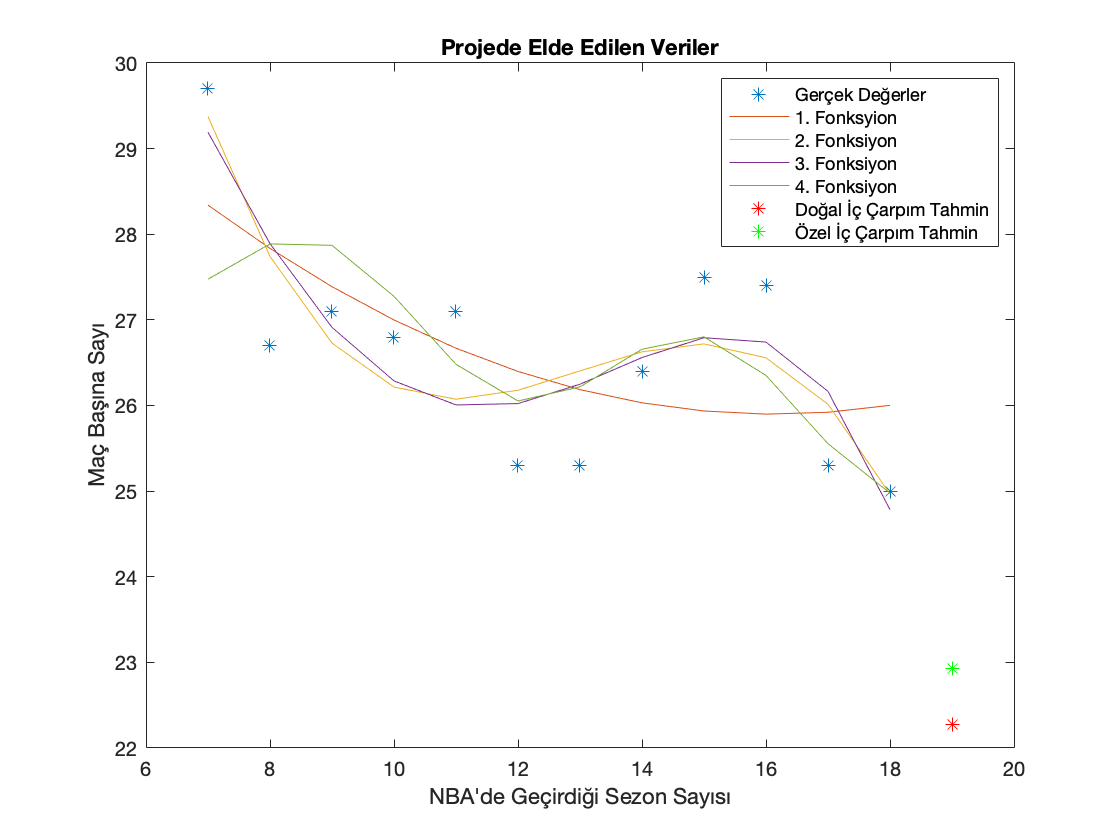

plot(x, y, "*");
hold on
plot(x, ypred1);
plot(x, ypred2);
plot(x, ypred3);
plot(x, ypred4);
plot(19, guesswnat, "*r");
plot(19, guesswnew, "*g");
title("Projede Elde Edilen Veriler");
ylabel("Maç Başına Sayı");
xlabel("NBA'de Geçirdiği Sezon Sayısı");
legend("Gerçek Değerler", "1. Fonksyion", "2. Fonksiyon", "3. Fonksiyon"...
    , "4. Fonksiyon", "Doğal İç Çarpım Tahmin", "Özel İç Çarpım Tahmin");

Bu projede LeBron James'in 12 sezonluk bir süreçte sezon başına averajladığı sayı miktarını lineer cebir metodlarını kullanarak değerlendirdik ve tahminlerde bulunduk.

Hazırlayanlar:

Uzay Karadağ 090200738

Erhan Turan 090200759

Muhammed Fatih Kaya 090200751